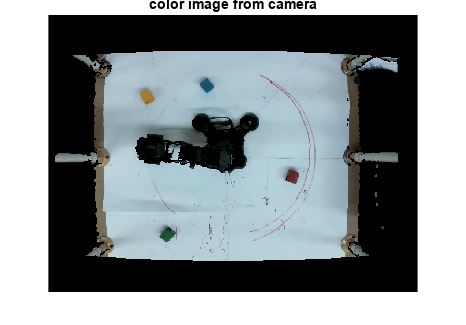

% show color image from camera
figure;
imshow(im)
title('color image from camera')

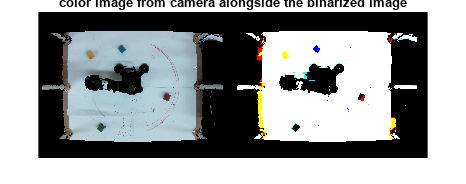


% binarize the image and show it along with color image
new_img = imbinarize(im);
figure;
imshowpair(im, new_img,'montage');
title('color image from camera alongside the binarized image')

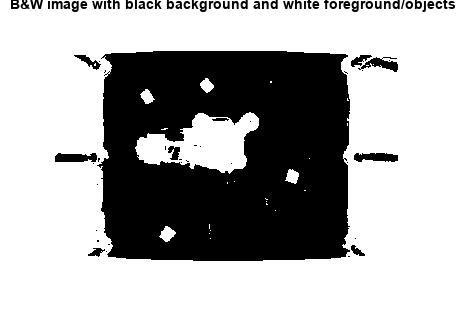


% getting a b&w image with black background and white foreground/objects
bw=~(new_img(:,:,1)&new_img(:,:,2)&new_img(:,:,3));
figure;
imshow(bw)
title('B&W image with black background and white foreground/objects')

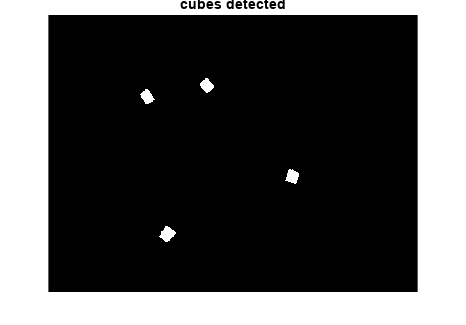


% applying the connected components function to the b&w image to get the number of objects in the image and their pixel data
tmp = bwconncomp(bw);

% making for loop to detect the cubes:
for i=1:tmp.NumObjects % iterating through all objects
    if ((length(tmp.PixelIdxList{i}) < 100) || (length(tmp.PixelIdxList{i}) > 1000)) % if the value of pixels is not between 100 and 1000 then it is not a cube
        bw(tmp.PixelIdxList{i}) = 0; % turn the area which is not a cube object into black
    end
end

% showing the b&w image with only cubes in it
figure;
imshow(bw);
title('cubes detected')


% making sure we get the correct number of objects:
tmp = bwconncomp(bw); % outputs the number of cubes present in image
num_of_obj = tmp.NumObjects

num_of_obj = 4

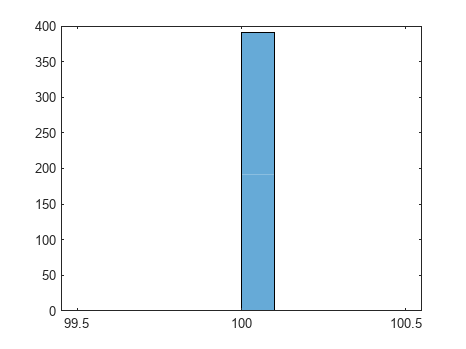

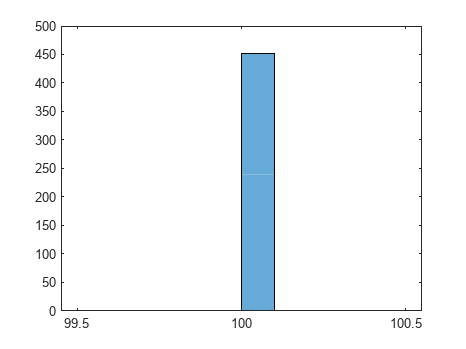

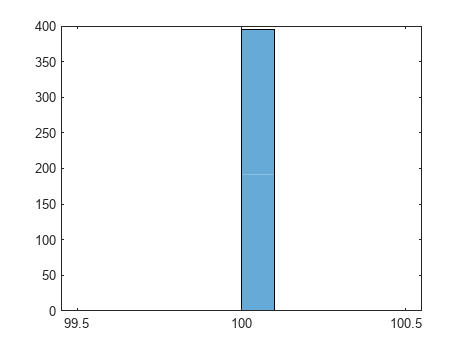

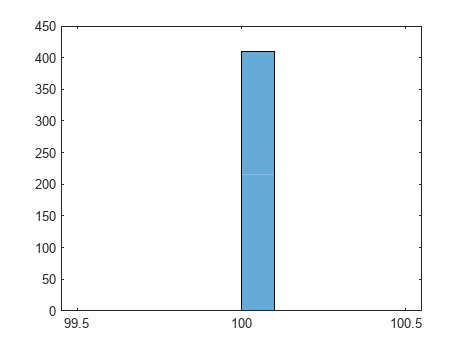


% separate rgb values from color image into 3 different variables
imred = im(:,:,1);
imgreen = im(:,:,2);
imblue = im(:,:,3);

% make 3 arrays for storing the means of rgb values for all objects
red = zeros(1,num_of_obj);
green = zeros(1,num_of_obj);
blue = zeros(1,num_of_obj);

% make arrays for storing the binary values of rgb for all objects
r = zeros(1,num_of_obj);
g = zeros(1,num_of_obj);
b = zeros(1,num_of_obj);

new_ig = ig*100; % to convert meters to centimeters

% for marking the center of each cube:
top = bw; % make a dummy variable to store the b&w image
top(:,:) = 0; % make the image completely black
% initialize array for row and column value of each object's centre point
rows = zeros(1,num_of_obj);
cols = zeros(1,num_of_obj);

% make for loop to store mean rgb values of the objects in the arrays created before
for i = 1:tmp.NumObjects
    red(i) = mean(imred(tmp.PixelIdxList{i}));
    green(i) = mean(imgreen(tmp.PixelIdxList{i}));
    blue(i) = mean(imblue(tmp.PixelIdxList{i}));

    % if rgb values above a certain threshold (i.e. 50) then make the binary value equal to 1 and otherwise 0
    if red(i) > 50
        r(i) = 1;
    end
    if green(i) > 50
        g(i) = 1;
    end
    if blue(i) > 50
        b(i) = 1;
    end
 
    a = []; % initialize an empty array

    % make a for loop to add non-zero pixels of all objects to the array
    for j = 1:length(tmp.PixelIdxList{i})
        if new_ig(tmp.PixelIdxList{i}(j)) ~= 0
            a(end+1) = new_ig(tmp.PixelIdxList{i}(j));
        end
    end

    % plot histograms of the pixel intensities of objects in the image
    figure
    temp = histogram(a ,10); % stores all data about the histograms
    [m, idx] = max(temp.Values); % get max value of pixel intensity of each object and store it in 'm.' also get it's index and store it in 'idx'
    sz = length(tmp.PixelIdxList{i}); % get the no. of pixels in each object

    j = 1; % initialize j from 1 as indexing starts from 1 in MATLAB

     % set threshold value of pixel intensity to be at an index 2 units more than index of max value
     thresh = temp.BinEdges(idx+2);

    % run while loop for all pixels of each object to only get the top face in image
    while j <= sz
        % if pixel value less than the threshold then its value is set to 1 (i.e. white)
        if ((new_ig(tmp.PixelIdxList{i}(j))) <= (thresh))
            top(tmp.PixelIdxList{i}(j)) = 1;
            j = j + 1;
        % otherwise the pixel is removed from the image altogether
        else
            tmp.PixelIdxList{i}(j) = [];
            sz = sz - 1;
        end
    end

    % get middle pixel values to get the centre point for each object
    x = ceil(mean(mod(tmp.PixelIdxList{i},480)));
    y = ceil(mean(ceil(tmp.PixelIdxList{i}/480)));
    rows(i) = x;
    cols(i) = y;
    % make the centre point equal to 0 (i.e. black)
    top(x,y) = 0;
end

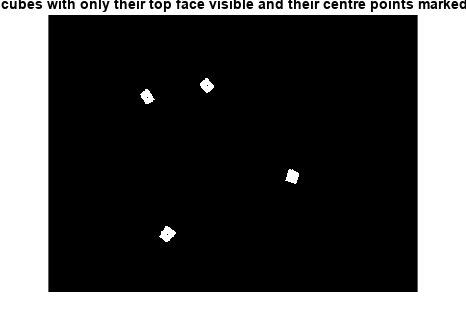


% display image of cubes with their top faces visible and also their centre points marked on them:
figure
imshow(top)
title('image of cubes with only their top face visible and their centre points marked on them')


% initialize variables to calculate no. of objects of each color in image
red_obj = 0;
green_obj = 0;
blue_obj = 0;
yellow_obj = 0;

% make a for loop to calculate no. of objects of each color in image
for i = 1:num_of_obj
    if (r(i) == 1) && (g(i) == 0) && (b(i) == 0)
        red_obj = red_obj + 1;
    end
    if (r(i) == 0) && (g(i) == 1) && (b(i) == 0)
        green_obj = green_obj + 1;
    end
    if (r(i) == 0) && (g(i) == 1) && (b(i) == 1) % blue is a different shade (i.e. cyan blue) so both green and blue value will be 1 
        blue_obj = blue_obj + 1;
    end
    if (r(i) == 1) && (g(i) == 1) && (b(i) == 0) % yellow is a mix of red and green so both red and green will be 1 for that
        yellow_obj = yellow_obj + 1;
    end
end

% output the no. of objects of each color in the image
red_obj

red_obj = 0

green_obj

green_obj = 0

blue_obj

blue_obj = 2

yellow_obj

yellow_obj = 0